% h=50
% V0x=20
% V0y=20
% g=9.81
% 
% t= 0: .2 :5.8
% x=V0x .* t
% y= h + (V0y .* t ) - ( g .* (t.^2))/2
% 
% plot(x,y)

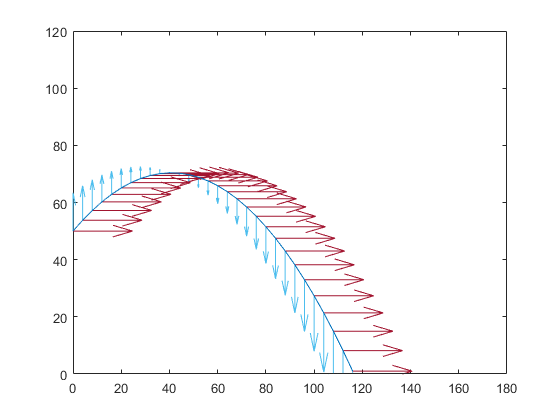

h=50;
V0x=20;
V0y=20;
g=9.81;

t= 0: .2 :5.8;
x=V0x .* t;
y= h + (V0y .* t ) - ( g .* (t.^2))/2;

hold on; % retenemos la grafica

% componentes en Y 
velY=V0y-g.*t; 
velX=0.*t; 
quiver(x,y,velX,velY,1);

% componentes en X
velY=0.*t;
velX=V0x-0.*t;  
quiver(x,y,velX,velY,1);


plot(x,y);

%ajustamos la grafica con el origen
xlim([0 180])
ylim([0 120])